clc;clear all;close all
%% N=5;A=[0 1;-3 -5];B=[0;1];C=[1 0];D=[0]
%% Ts=0.2;   %tf=1  Qy,R   %yrefk=1;    %(y-yref)'*Qy*(y-yref)+u'Ru
A=[0 1;-3 -5];B=[0;1];C=[1 0];D=[0]

D = 0

Ts=0.2;
%Fcosto  Qbig, q
Qy=100;
N=5;
R=0.1;
C'*Qy*C

ans =    100     0
     0     0


dC=diag(C'*Qy*C)

dC =    100
     0


%Qbig=diag([dC;dC;dC;dC;dC])
Qbig=blkdiag(kron(eye(N),C'*Qy*C),kron(eye(N),R))

Qbig =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   100     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0   100     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0   100     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


yrefk=1;
q=-[C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk;0;0;0;0;0]

q =   -100
     0
  -100
     0
  -100
     0
  -100
     0
  -100
     0


id=eye(2)

id =      1     0
     0     1


ze=zeros(2);
zeB=0*B;
Ad=A*Ts+id;
Bd=B*Ts;
Aeq=[-id ze ze ze ze Bd zeB zeB zeB zeB;
     Ad -id ze ze ze zeB Bd zeB zeB zeB;
     ze Ad -id ze ze zeB zeB Bd zeB zeB;
     ze ze Ad -id ze zeB zeB zeB Bd zeB;
     ze ze ze Ad -id zeB zeB zeB zeB Bd;]

Aeq =    -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0000         0         0         0         0         0         0         0         0    0.2000         0         0         0         0
    1.0000    0.2000   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0
   -0.6000         0         0   -1.0000         0         0         0         0         0         0         0    0.2000         0         0         0
         0         0    1.0000    0.2000   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0   -0.6000         0         0   -1.0000         0         0         0         0         0         0    0.2000         0         0
         0         0         0         0    1.0000    0.2000   -1.0000         0        

x0=[0;0];
zex0=0*x0;
beq=[-Ad*x0;zex0;zex0;zex0;zex0]

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z=quadprog(Qbig,q,[],[],Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =          0
    3.4915
    0.6983
    1.1546
    0.9292
    0.2203
    0.9733
   -0.1322
    0.9468
   -0.5840


X=z(1:10)

X =          0
    3.4915
    0.6983
    1.1546
    0.9292
    0.2203
    0.9733
   -0.1322
    0.9468
   -0.5840


U=z(10+(1:5))

U =    17.4574
    5.7728
    3.1963
    2.1268
         0


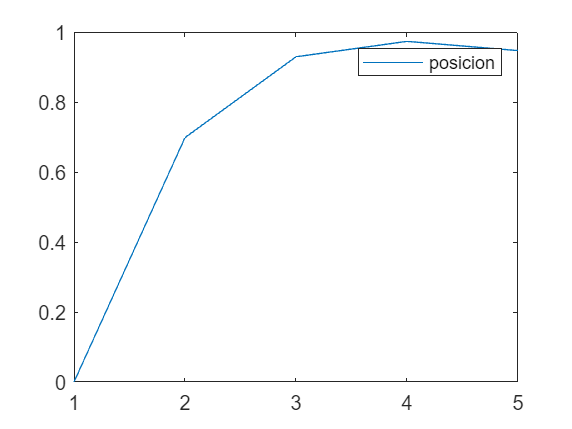

figure
plot(X(1:2:end));
legend('posicion')

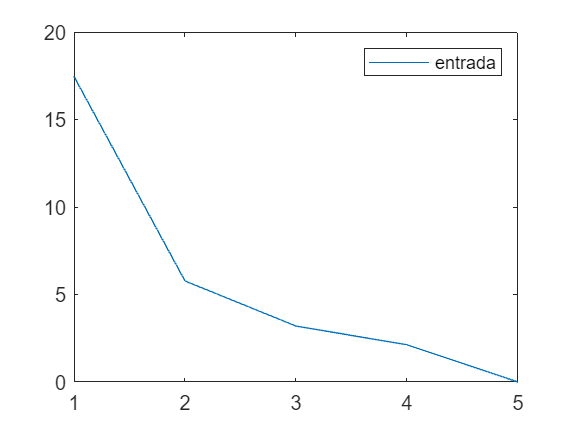

figure
plot(U)
legend('entrada')

%EJEMPLO CON RESTRICCIONES
ze=[0 0];
id=1;
zeB=0;
Ades=[ze ze ze ze ze id zeB zeB zeB zeB;
     ze ze ze ze ze zeB id zeB zeB zeB;
     ze ze ze ze ze zeB zeB id zeB zeB;
     ze ze ze ze ze zeB zeB zeB id zeB;
     ze ze ze ze ze zeB zeB zeB zeB id;]

Ades =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


bdes=[10;10;10;10;10]

bdes =     10
    10
    10
    10
    10


z=quadprog(Qbig,q,Ades,bdes,Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =          0
    2.0000
    0.4000
    2.0000
    0.8000
    0.7062
    0.9412
   -0.0038
    0.9405
   -0.5647


X=z(1:10)

X =          0
    2.0000
    0.4000
    2.0000
    0.8000
    0.7062
    0.9412
   -0.0038
    0.9405
   -0.5647


U=z(10+(1:5))

U =    10.0000
   10.0000
    4.7311
    2.3809
   -0.0000


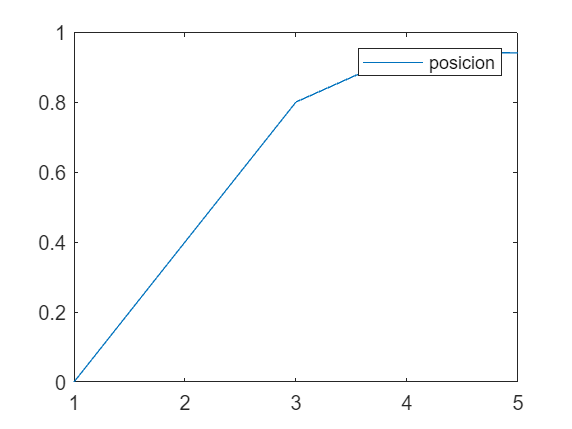

figure
plot(X(1:2:end));
legend('posicion')

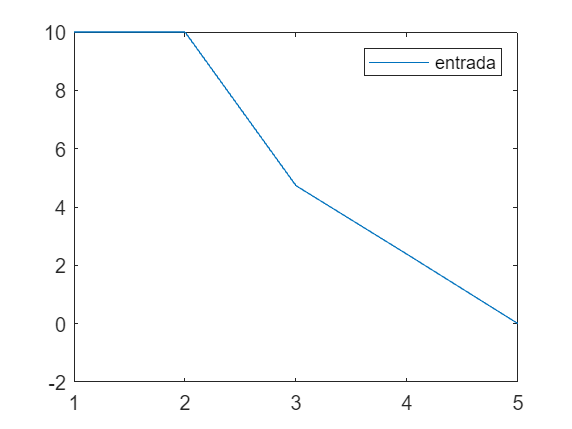

figure
plot(U)
legend('entrada')